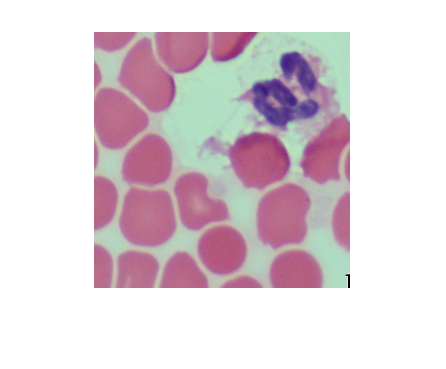

i = 2;
project_loc = "C:\Users\raj20\OneDrive\Desktop\IP\";

img = imread(project_loc + "Dataset\images\image-"+ i +".png");
imshow(img)

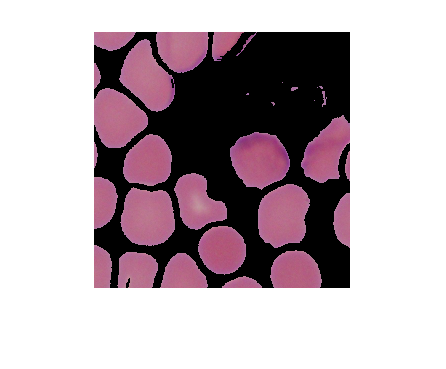

[RBC_BinaryMask, RBC_RGBMask] = RBCMask(img);
imshow(RBC_RGBMask)

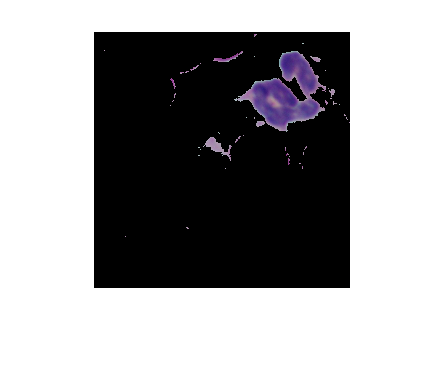

[WBC_BinaryMask, WBC_RGBMask] = WBCMask(img);
imshow(WBC_RGBMask)

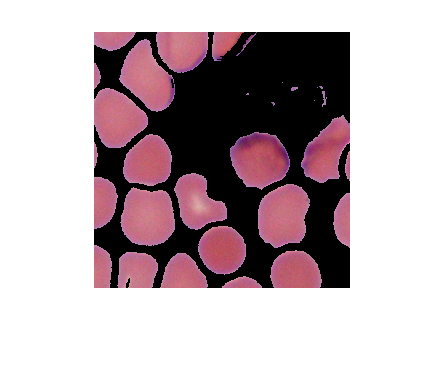

RBC_Enh_RGBMask = EnhanceRGB(RBC_RGBMask, 2/3, 1.15);
imshow(RBC_Enh_RGBMask)

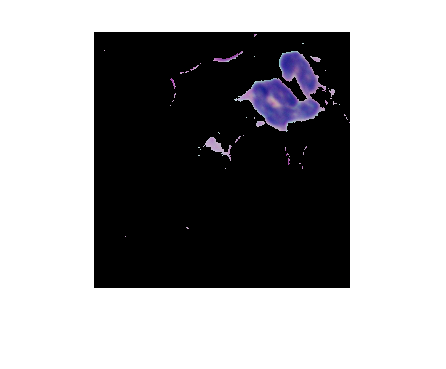

WBC_Enh_RGBMask = EnhanceRGB(WBC_RGBMask, 5/8, 1.15);
imshow(WBC_Enh_RGBMask)

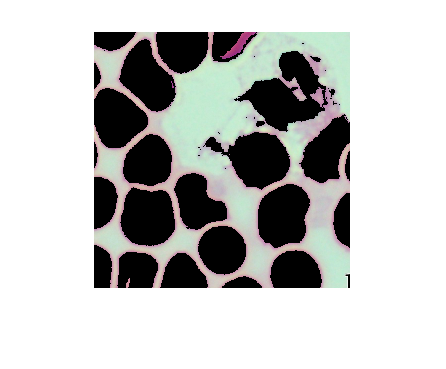

RBC_WBC_BinaryMask = logical(RBC_BinaryMask) | logical(WBC_BinaryMask);
BackgroundBinaryMask = logical(img) - logical(RBC_WBC_BinaryMask);
Background_RGBMask = img;
Background_RGBMask(~BackgroundBinaryMask) = 0;
Background_Enh_RGBMask = EnhanceRGB(Background_RGBMask, 0.01, 1.1);
imshow(Background_Enh_RGBMask)

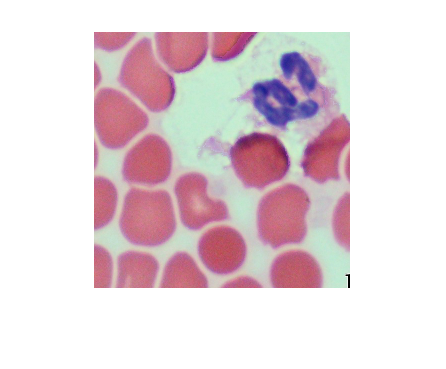

Result = Background_Enh_RGBMask;
for l3 = 1:3
    for l2 = 1:256
        for l1 = 1:256
            if Background_Enh_RGBMask(l1, l2, l3) == 0
                if WBC_Enh_RGBMask(l1, l2, l3) == 0
                    Result(l1, l2, l3) = RBC_Enh_RGBMask(l1, l2, l3);
                else
                    Result(l1, l2, l3) = WBC_Enh_RGBMask(l1, l2, l3);
                end
            end
        end
    end
end
imshow(Result)

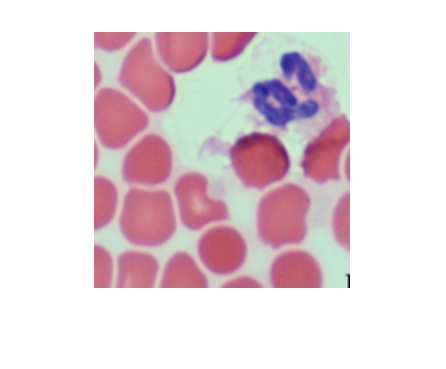

dim = 3;
filter = ones(dim) / (dim^2);
final_image = imfilter(Result, filter, "symmetric");
imshow(final_image)

imshow(img)